## Task 1

%1.a. 
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = [1500, 1600, 1700, 1800, 1900];  % Values for packet rate in pps
f = 1000000;                              % Queue size(in bytes)
b = 10^-6;                                % Bit Error Rate

N = 20;                                   % number of simulation

pkt_delay = zeros(1, length(lambda));
error_delay = zeros(1, length(lambda));
pkt_loss = zeros(1,length(lambda));
error_loss = zeros(1,length(lambda));

for i = 1:length(lambda)

    PL = zeros(1, N);
    APD = zeros(1, N);
    MPD = zeros(1, N);
    TT = zeros(1, N);
    
    for j = 1:N
        [PL(j), APD(j), MPD(j), TT(j)] = Simulator2(lambda(i), C, f, P, b);
    end

    alfa = 0.1; % 90% confidence interval

    AVERAGE = mean(PL);
    TERM = norminv(1-alfa/2)*sqrt(var(PL)/N);
    fprintf("Packet Loss (%%)       = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss(i) = AVERAGE;
    error_loss(i) = TERM;

    AVERAGE = mean(APD);
    TERM = norminv(1-alfa/2)*sqrt(var(APD)/N);
    fprintf("Av. Packet Delay (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay(i) = AVERAGE;
    error_delay(i) = TERM;

end

Packet Loss (%)       = 4.84e-01 +- 7.62e-03


Av. Packet Delay (ms)  = 1.85e+00 +- 1.41e-02


Packet Loss (%)       = 4.98e-01 +- 6.67e-03


Av. Packet Delay (ms)  = 2.29e+00 +- 2.35e-02


Packet Loss (%)       = 4.91e-01 +- 8.20e-03


Av. Packet Delay (ms)  = 2.99e+00 +- 3.50e-02


Packet Loss (%)       = 4.96e-01 +- 6.77e-03


Av. Packet Delay (ms)  = 4.42e+00 +- 9.24e-02


Packet Loss (%)       = 4.85e-01 +- 7.19e-03


Av. Packet Delay (ms)  = 8.33e+00 +- 4.28e-01


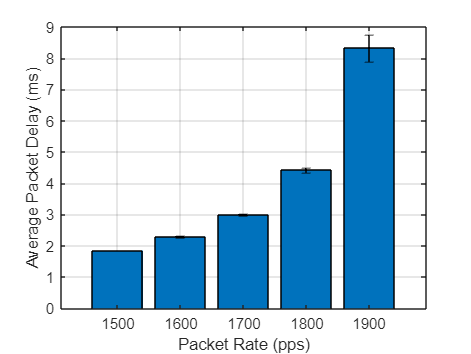


figure(1)
bar(categorical(lambda), pkt_delay)
xlabel("Packet Rate (pps)")
ylabel("Average Packet Delay (ms)")
hold on
er = errorbar(categorical(lambda), pkt_delay, error_delay, error_delay);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

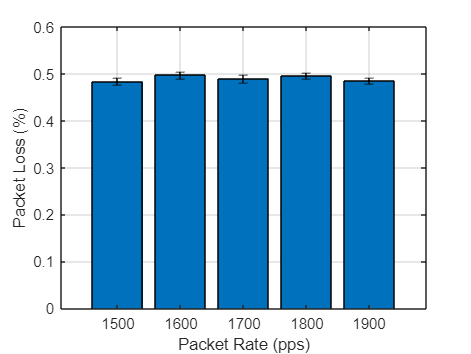


%%% Plot the results
figure(2)
bar(categorical(lambda), pkt_loss)
xlabel("Packet Rate (pps)")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(lambda), pkt_loss, error_loss, error_loss);
er.Color = [0 0 0];
er.LineStyle = 'none';
grid on;
hold off;

fprintf("-------------------------------------------")

-------------------------------------------

%%% conclusão: nota-se que a capacidade do link e tamanho de queue fixas, 
% o atraso médio dos pacotes aumente à medida que a taxa de chegada dos
% mesmos aumenta(i.e, a medida que packet rate aumenta).